# TUTORIAL: Fitting Multinomial Logistic Regression Models to Behavioural Data Using Dummy Coding in MATLAB

## What is Multinomial Logistic Regression?

In statistical analysis, **regression** models are a way of estimating the relationship between an outcome of interest, the so-called **dependent variable**, and one or more predictors a.k.a. **independent variables**. To do this requires observations of different outcomes Y paired with measurements X, to which a model is then fitted to predict Y from X. The most famous example of regression is probably the **simple linear regression** in which both the independent and dependent variable are continuous quantities, such as when trying to predict weight based on height. The resulting regression model will then be of the form:


$$y=\beta_0 +\beta_{1\;} x$$


a simple trend line with an intercept $\beta_0$ and a slope $\beta_1$, the central question, which applies to any regression model, being to find the values of these parameters which produce the best prediction given a set of data points. A first extension that can be made to this model is to admit multiple predictors $x_1 {,\;x}_2 ,\ldotp \ldotp \ldotp x_p$, in which case the model will look something like:


$$y=\beta_0 +\beta_{1\;} x_{1\;\;} +\beta_{2\;} x_2 +\ldotp \ldotp \ldotp +\beta_p x_{p\;}$$


Sometimes the variable we want to predict is not a continuous quantity like height but a category or **nominal variable**. In the simplest cases, there are only two categories, for instance 'smoker' vs. 'non-smoker', 'yes' vs. 'no', etc. In this case, the trick at the heart of **logistic regression** is to perform a linear regression, not on the binary outcomes themselves which are not quantities, but on the probability or more precisely the log-odds of the outcomes, for instance:


$$\log \left(\frac{p\left(Y=\;\textrm{yes}\right)}{p\left(Y=\;\textrm{no}\right)}\right)=\beta_{0\;} +\beta_{1\;} x_1 +\ldotp \ldotp \ldotp +\beta_{n\;} x_{n\;}$$


A **multinomial logistic regression** is used when there are more than two categorical outcomes. In this case, the log-odds have to be estimated with reference to a reference outcome, and the model is a system of equations with as many equations as there are non-reference outcomes. For instance, in the case I will be working here, we will be looking at the probabilities of choosing levers in a 3-armed bandit task. The outcome at a given trial is indeed nominal, e.g. the agent chose lever 1, and since we have three possible choices, we want to find the parameters of a system of 2 equations which, assuming we took lever 3 as reference, would be:


$$\left\lbrace \begin{array}{ll}
\log \left(\frac{P\left(\textrm{lever}\;1\right)}{P\left(\textrm{lever}\;3\right)}\right)=\beta_{1,0} +\beta_{1,1} \;x_1 +\beta_{1,2} x_2 +\ldotp \ldotp \ldotp +\beta_{1,n\;} x_{1,n} =\eta_1  & \\
\log \left(\frac{P\left(\textrm{lever}\;2\right)}{P\left(\textrm{lever}\;3\right)}\right)=\beta_{2,0} +\beta_{2,1} \;x_1 +\beta_{2,2} x_2 +\ldotp \ldotp \ldotp +\beta_{2,n\;} x_{1,n} =\eta_2  & 
\end{array}\right.$$


Once the parameters are found and using the fact that $P\left(\textrm{lever}\;1\right)+P\left(\textrm{lever}\;2\right)+P\left(\textrm{lever}\;3\right)=1$, you can find the estimated probability of each action:


$$\begin{cases}
P(lever _1) = \frac{e^{\eta_1}}{1 + e^{\eta_1} + e^{\eta_2}} \\
P(lever_2) = \frac{e^{\eta_2}}{1 + e^{\eta_1} + e^{\eta_2}} \\
P(lever_3) = \frac{1}{1 + e^{\eta_1} + e^{\eta_2}} \\
\end{cases}$$


## Dummy Coding

I've explained how to deal with nominal dependent variables, now comes the turn of nominal independent variables. We cannot use the same trick that dealt with nominal dependent models in logistic regression which consists in replacing categories with probabilities, because the categories of the independent variables belong to data points about which there is no uncertainty. Instead, we use **dummy coding**, a technique that simply replaces nominal variables by 0 or 1 (sometimes -1 if two predictors are expected to have antagonistic effects) to indicate whether a data point belongs or not to that category. If there are n categories, then n-1 such dummy variables are needed, the missing category being the reference or default. For example, if we want to predict height based on sex, we could introduce a dummy variable x equal to 1 if the subject is female and 0 if male; the model would be:


$$y=\beta_0 +\beta_1 x$$
 

The meaning and value of $\beta_{0\;}$and $\beta_1 \;$should now be obvious: if the individual is male, we have $y=\beta_0$ so that $\beta_0$ is just your best prediction of an individual's height knowing he is male, so the mean height (for this sample of males); conversely for a female, $y=\beta_0 +\beta_1$ which means that $\beta_1$must be the difference in mean height between females and males.

## A small Simulated Dataset

We are now ready to tackle the main objective of this tutorial which is to optimise a multinomial logistic regression on data collected in a **multi-armed bandit task**.These tasks, which are a classic **reinforcement learning** problem commonly used in neuroscience, are made of discrete trials in which subjects have to choose one action among several in the hope of obtaining a reward. Using past rewards and choices as predictors in a logistic regression model can be used to determine the impact of these past events on current choices as in the study of Lau and Glimcher (2005) which used logistic regression to study a two-armed bandit task and found that the impact of past rewards decayed in an approximately exponential way. This study inspired me to test a more complex multinomial logistic regression on a three-armed bandit task, which proved to be a more difficult challenge than initially expected.

To start with, we shall need data, which will be a simple synthetic collection of 900 trials with recorded choices and rewards. This virtual experiment will consist of blocks of 100 trials during which one of the levers will be rewarded with a 60% probability if selected, while the two others will be rewarded with a probability of 20% each. To generate plausibly realistic choices, we will use a Q-learning model with a learning rate of 0.1 that also serves as a forgetting rate for non-selected actions, paired with a softmax action selection with an inverse temperature of 5. If you do not understand what this all means, all you need to know is that this is a way of generating interesting data.

%% Simulate some behavioural data

rng(1);  % make the example reproducible

trials_per_block = 100;
schedule = repmat([1, 2, 3], 1, 3); % identities of the best lever in each block of trials
n_blocks = length(schedule);
n_trials = n_blocks * trials_per_block;

data = struct('choices', nan(n_trials, 1), 'rewards', nan(n_trials,1)); % column 1 for choices, column 2 for rewards

% initialise the Q-learner
Q = zeros(1, 3);
learningRate = 0.1;
inverseTemperature = 5;

for trial = 1 : n_trials
    
    % given trial number, get the current best lever
    block = ceil(trial / trials_per_block);
    best = schedule(block);
    
    % generate a random choice based on current Q-values
    probs = exp(inverseTemperature * Q) ./ sum(exp(inverseTemperature * Q));
    choice = randsample(1:3, 1, true, probs);
    
    % generate a stochastic reward based on the choice
    reward = rand < (choice == best) * 0.6 + (choice ~= best) * 0.2;

    % update Q-values for next step
    Q = (1 - learningRate) * Q; % forgetting step that applies to all levers
    Q(choice) = Q(choice) + learningRate * reward; % learning that applies only to the selected lever    
   
    % store trial observations
    data.choices(trial) = choice;
    data.rewards(trial) = reward;
end


To get an idea of what this data looks like, here is a quick plot of the rates of selection of each lever using 20-trial centred-window moving averages. You should see distinct periods in which the three levers dominate in turn for blocks of roughly 100 trials illustrating how the Q-learning algorithm manages to keep track of the reward schedule.

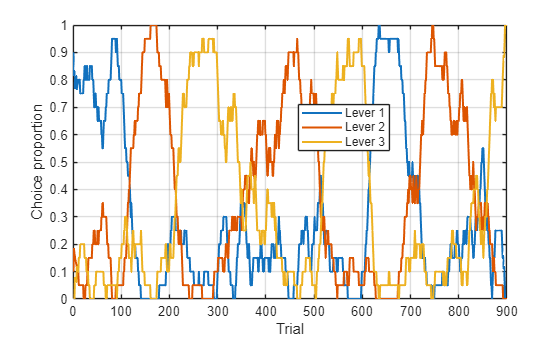

%% running averages of lever selection for quick visualisation

figure()
windowSize = 20;
runningChoiceRate = movmean(data.choices == (1:3), windowSize, 1);

plot(runningChoiceRate, 'LineWidth', 1.5);
xlabel('Trial');
ylabel('Choice proportion');
legend('Lever 1', 'Lever 2', 'Lever 3', 'Location', 'best');
grid on;

## **Constructing the Design Matrix**

We now ask whether previous choices and rewards can predict the choice on the current trial. At this point, the design of the regression is really up to you. In my case, I want to use the past 10 trials (the horizon) to predict choices based on 5 predictors for each past trial up: indicators for `choosing lever 1`, `choosing lever 2`, `being rewarded on lever 1`, `being rewarded on lever 2`, and `being rewarded on lever 3`. A few things to note about this design are that there is no predictor for choosing lever 3, which means choosing lever 3 is the reference lever as in the beginning, and that the last three predictors are choice-reward combinations: predictor 3 is the effect of being rewarded on lever 1 in addition to the effect of selecting lever 1 which is predictor 1. Alternative designs might want to separate these effects separately, and they matter when trying to interpret the final results. Given this design, each past trial in the horizon contributes five columns to our **design matrix X** which is the sequence of predictors (columns) for each observation rows :

horizon = 10;
n_levers = 3;
ref_lever = 3;
non_ref_levers = setdiff(1:n_levers, ref_lever);

n_choice_cols = n_levers - 1;
n_reward_cols = n_levers;

cols_per_lag = n_choice_cols + n_reward_cols;
n_pred = cols_per_lag * horizon;

We can now construct `X` and `y`.

% We lose the first 'horizon' trials because there is not enough previous history to construct the predictors.
n_rows = n_trials - horizon;

X = zeros(n_rows, n_pred);
y = zeros(n_rows, 1);

row = 1;

for t = horizon + 1 : n_trials % we go through trials filling in the rows of X and Y
    
    % Current choice is the response variable
    y(row) = data.choices(t);
    
    % -------------------------------------------------------------
    % Construct predictors from previous trials
    % -------------------------------------------------------------
    
    for k = 1 : horizon % we repeat these same steps for each lag trial in turn
        
        % First column belonging to this lag
        lag_offset = (k-1) * cols_per_lag;
        
        past_choice = data.choices(t-k);
        past_reward = data.rewards(t-k);
        
        % ---------------------------------------------------------
        % Previous choice
        % ---------------------------------------------------------
        
        % Lever 3 is the reference category, so it does not get
        % its own dummy variable.
        if past_choice == 1
            X(row, lag_offset + 1) = 1;
        elseif past_choice == 2
            X(row, lag_offset + 2) = 1;
        end
        
        % ---------------------------------------------------------
        % Previous rewarded choice
        % ---------------------------------------------------------
        
        % If the previous choice was rewarded, activate the
        % indicator corresponding to the chosen lever.
        if past_reward == 1            
            reward_col = lag_offset + ...
                n_choice_cols + past_choice;            
            X(row, reward_col) = 1;            
        end        
    end    
    row = row + 1;
end

## Fitting the Regression Model

We have now built our design matrix X which contains the agent's behavioural history, and y which contains the choice made on the current trial. For horizon = 10, there are: 5 predictors per lag × 10 lags = 50 predictors so X has 50 columns. The first five columns describe the immediately preceding trial, the next five describe the trial before that, and so on. To fit the multinomial regression model we use the built-in `mnrfit` function. Recent MATLAB releases also provide a more recent `fitmnr` function, but I chose `mnrfit` because constructing the dummy-coded design matrix X makes the predictor encoding more transparent.

% Fit the multinomial logistic regression
[B, ~, ~] = mnrfit(X, y);


The output B contains the fitted coefficients of the model. It has two columns, the first for the log-odds of choosing lever 1 rather than lever 3, and its second for the log-odds of lever 2 over lever 3. It contains 51 rows, the first row is for the intercepts $\beta_{1,0}$ and $\beta_{2,0}$, and the remaining 50 for the predictor coefficients. To check the model is working, you can calculate and plot the predicted probabilities of each action using the `mnrval` function, the fitted B, and the original data X (instead of recycling X, the recommended method is usually to hold out some of the data from the fitting and to use that as a test dataset).

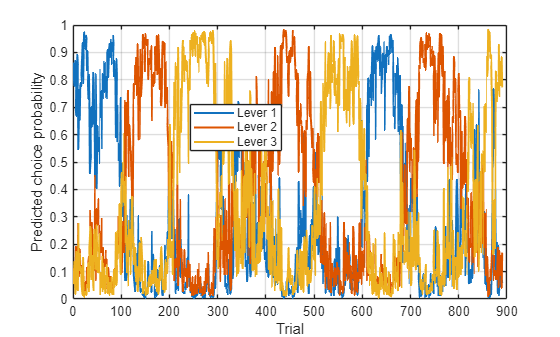

% Evaluate fitted choice probabilities on the observed predictors

P = mnrval(B, X);

figure()
plot(P, 'LineWidth', 1.5);
xlabel('Trial');
ylabel('Predicted choice probability');
legend('Lever 1', 'Lever 2', 'Lever 3', 'Location', 'best');
grid on;

Compared to the running averages we plotted before, the fitted probabilities reproduce broad patterns of the original data. We see dominance of the different levers alternating between blocks, and, unless you have changed the random seed, you should see that the fourth block, in which the agent for some random reason had trouble picking the correct lever 1, is also ambiguous from the fitted model's point of view, thus matching an idiosyncratic feature of the original data.

## A Misguided Attempt to Interpret the Fitted Model

Following the example of Lau and Glimcher, you might want to simply plot some of the fitted coefficients to see how past predictors affect choices. An obvious strategy could be to look at the separate impacts of being rewarded on a lever and of selecting a lever without necessarily being rewarded on the log-odds of that same lever, as measurements of the effects of reinforcement and choice persistance on behaviour. In the case of lever 1, the coefficients for the predictor `lever 1 chosen` are found at indices 2, 7, 12, etc. of B and the coefficients for the predictor `lever 1 rewarded` at indices 4, 9, 14, etc. For lever 2, we are interested with the coefficients of `lever 2 chosen` (indices 3, 8, 13, ...) and `lever 2 rewarded` (indices 5, 10, 15, ...).

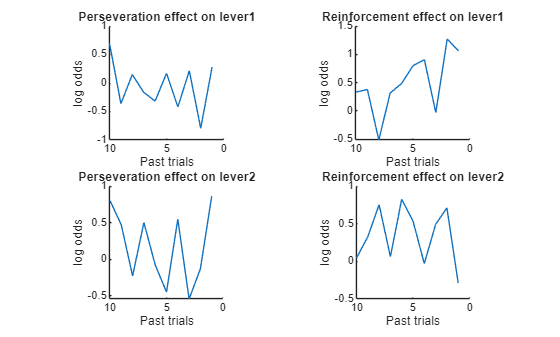

figure()

subplot(2,2,1)
hold on
plot(1 : horizon, B(2 : cols_per_lag : end,1))
title('Perseveration effect on lever1')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,2)
hold on
plot(1 : horizon, B(4 : cols_per_lag : end,1))
title('Reinforcement effect on lever1')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,3)
hold on
plot(1 : horizon, B(3 : cols_per_lag : end,2))
title('Perseveration effect on lever2')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

subplot(2,2,4)
hold on
plot(1 : horizon, B(5 : cols_per_lag : end,2))
title('Reinforcement effect on lever2')
xlabel('Past trials')
ylabel('log odds')
set(gca,'XDir', 'reverse')
axis square

While the other coefficients have little obvious trend, the coefficients associated with rewarded choices on lever 1 are positive and tend to decrease as we look further into the past, suggesting a positive and decreasing impact of past rewards on selecting lever 1. However, contrary to the original study of Lau and Glimcher which relied on a simple logistic regression with just two possible outcomes, interpretation of this observation is more delicate as these coefficients tell us how the lever 1 versus lever 3 log-odds contrast is affected, rather than how choice probability, the quantity we are really interested in, behaves, which might explain why the other coefficients seem noisy at first glance. To know this, we must take into account the other alternatives, a topic for another time.